Date: 6/29/2020

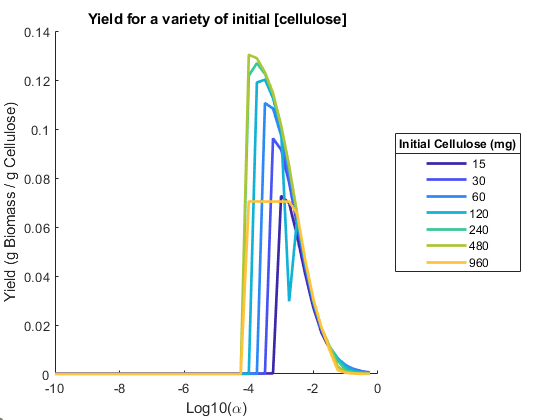

Problem Description: Yield for the series that has the highest cellulose amount becomes limited

Data details:

- Cellulolysis kinetic parameters taken from literature

-     KM = 0.2mg/mL, 5.6e-3mM

-     kcat = 32 s^-1

- Initial Mannose is 20x the initial biomass by weight = 0.0150mmoles

- Nongrowth associciated maintenance (NGAM) set to 0.7, GAM set to 23.49

- No initial glucose or enzyme

- Initial population 1.35e-4 g

Data available as diagnosis/DataAnomalies/table_dat3_litparam_growthdropoff.mat

**Part 1:** Run it again locally, see if this still happens.

Note: Version of the comets_branch.jar on SCC1 has been updated as part of the fix to dat3_litparam_growthdropoff.mlx, it is now a copy of the version used locally on BNF_MQUINTIN as of 6/29/2020

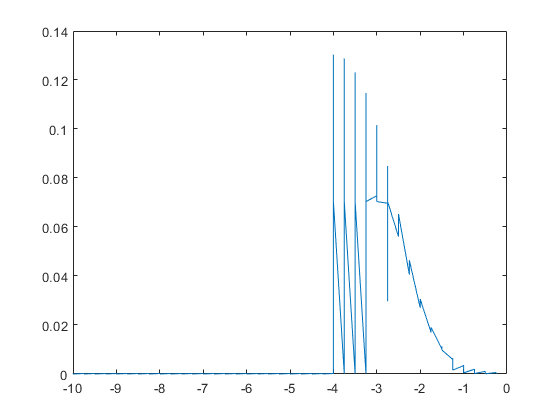

load ("diagnosis/DataAnomalies/dat3_litParams_mannose20x.mat");
plot(log10(dat3.alpha),dat3.yield)

rnum = (log10(dat3.alpha)==-3.5 & dat3.celscale == max(dat3.celscale));
row = dat3(rnum,:);

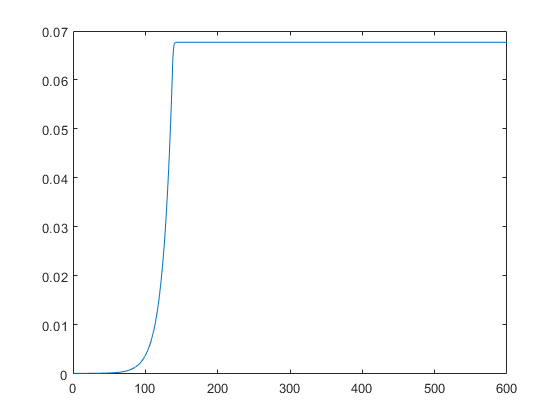

%check growth and media components
plot(row.t{1},row.biomass{1});

plot(row.t{1},horzcat(row.glc_amt{1},row.cellulose_amt{1},row.enzyme_amt{1},row.etoh_amt{1}));
leg = legend({'Glc';'Cel';'Enz';'EtOH'},'location','southoutside','Orientation','horizontal')

leg =   Legend (Glc, Cel, Enz, EtOH) with properties:

         String: {'Glc'  'Cel'  'Enz'  'EtOH'}
       Location: 'southoutside'
    Orientation: 'horizontal'
       FontSize: 9
       Position: [0.2571 0.0952 0.5214 0.0476]
          Units: 'normalized'

  Show all properties


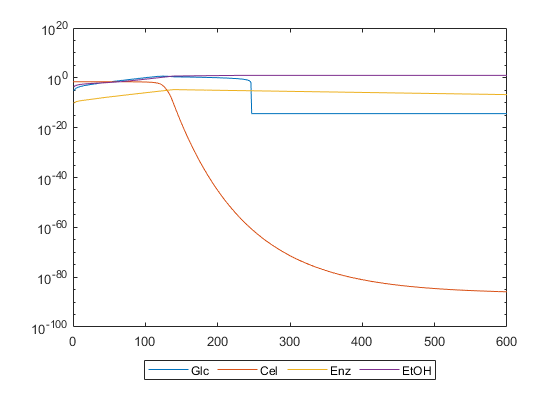

set(gca,'yscale','log');

%get a closer look at glucose and ethanol
plot(row.t{1},horzcat(row.glc_amt{1},row.etoh_amt{1}),'LineWidth',2);
leg = legend({'Glc';'EtOH'},'location','southoutside')

leg =   Legend (Glc, EtOH) with properties:

         String: {'Glc'  'EtOH'}
       Location: 'southoutside'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.4455 0.0917 0.1446 0.0869]
          Units: 'normalized'

  Show all properties


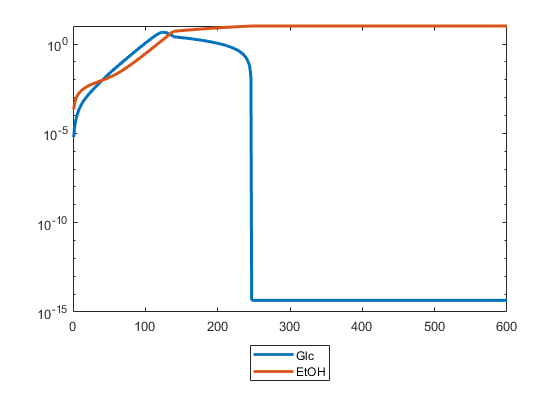

set(gca,'yscale','log');

**Part 1: Run it again, capture the full media**

v = args.p3.v;
v.NGAM = 0.7;
v.GAM = 23.49;
v.kcat_cel = row.kcat_cel(1);
v.km_cel = row.km_cel(1);
v.initcellulose = row.initcel(1);
v.alpha = row.alpha(1);
v.maxcycles = 500;

model = prepareYeastGEMModel('v',v);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

layout = buildCelOptLayout(model);

cd 'C:\sync\biomes\cellulose\optima\temp';
runComets(layout);

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


bio = parseBiomassLog(layout.params.biomassLogName);
media = parseMediaLog(layout.params.mediaLogName);

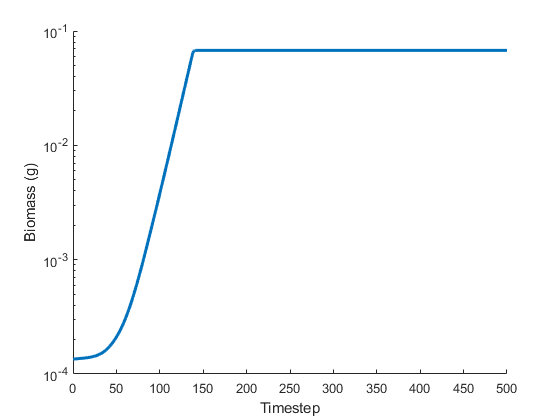

figure();
plotBiomassTimecourse(bio);

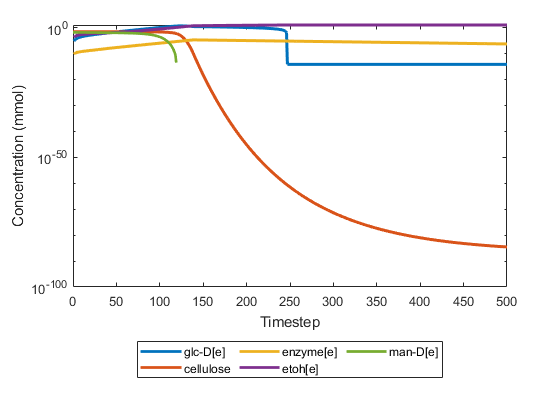

figure();
plotMediaTimecourse(media,{'glc-D[e]','cellulose','enzyme[e]','etoh[e]','man-D[e]',},'l');

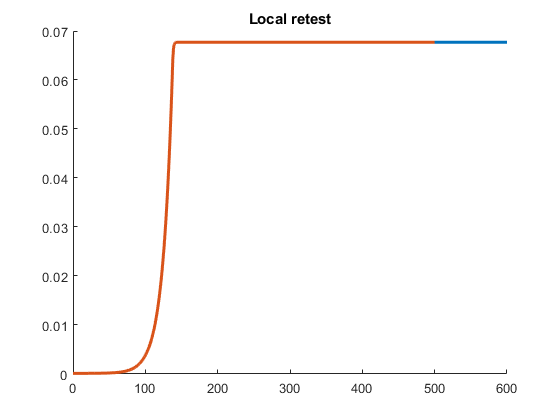

%compare retest vs original
figure();
hold on;
title('Local retest');
plot(row.t{1},row.biomass{1},'linewidth',2);
plot(bio.t,bio.biomass,'linewidth',2);
hold off;

Compare vs local retest using 1/4 as much cellulose

v.initcellulose = row.initcel(1) / 4;
model_qtr = prepareYeastGEMModel('v',v);

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51

layout_qtr = buildCelOptLayout(model_qtr);
cd 'C:\sync\biomes\cellulose\optima\temp';
runComets(layout_qtr);

Log file C:\sync\biomes\cellulose\optima\temp\log_media.m already exists! Deleting it before COMETS execution...
Log file C:\sync\biomes\cellulose\optima\temp\log_biomass.m already exists! Deleting it before COMETS execution...
Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


bio_qtr = parseBiomassLog(layout_qtr.params.biomassLogName);
media_qtr = parseMediaLog(layout_qtr.params.mediaLogName);

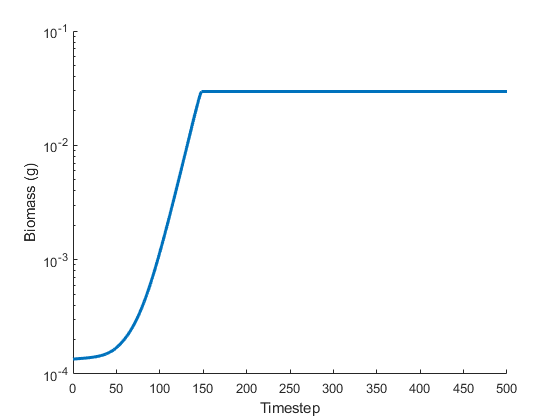

figure();
plotBiomassTimecourse(bio_qtr);

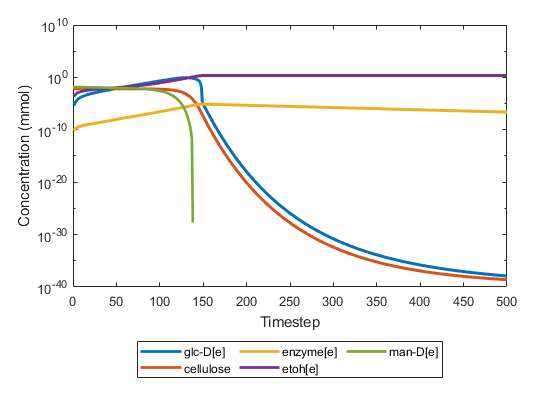

figure();
plotMediaTimecourse(media_qtr,{'glc-D[e]','cellulose','enzyme[e]','etoh[e]','man-D[e]',},'l');

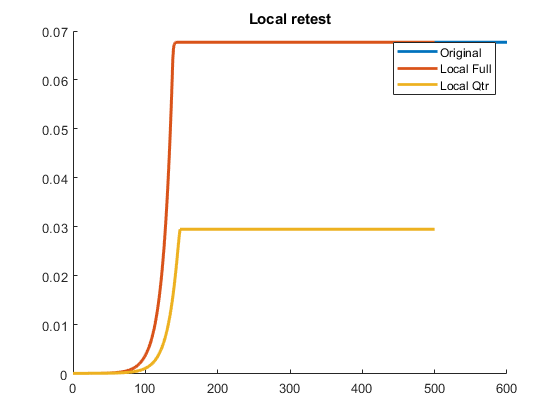

%compare retest vs original
figure();
hold on;
title('Local retest');
plot(row.t{1},row.biomass{1},'linewidth',2);
plot(bio.t,bio.biomass,'linewidth',2);
plot(bio_qtr.t,bio_qtr.biomass,'linewidth',2);
leg = legend({'Original';'Local Full';'Local Qtr'});
hold off;